1번

A1 = [1 4 2; 2 4 100; 7 9 7; 3 pi 42];
B1 = log(A1);

row2_B = B1(2, :)

row2_B =     0.6931    1.3863    4.6052



row2_B_sum = sum(row2_B)

row2_B_sum = 6.6846


col_mul = B1(:, 2) .* A1(:, 1)

col_mul =     1.3863
    2.7726
   15.3806
    3.4342



max_vec = max(col_mul)

max_vec = 15.3806


div_vec = A1(1, :) ./ B1(1:3,3);
div_vec_sum = sum(div_vec)

div_vec_sum =     2.1737    8.6950    4.3475


2번

v02 = 50;
A2 = deg2rad(50);
g2 = 9.81;

thit = (2*v02*sin(A2)) / g2

thit = 7.8088

ymax = (v02 * sin(A2))^2 / (2 * g2)

ymax = 74.7737

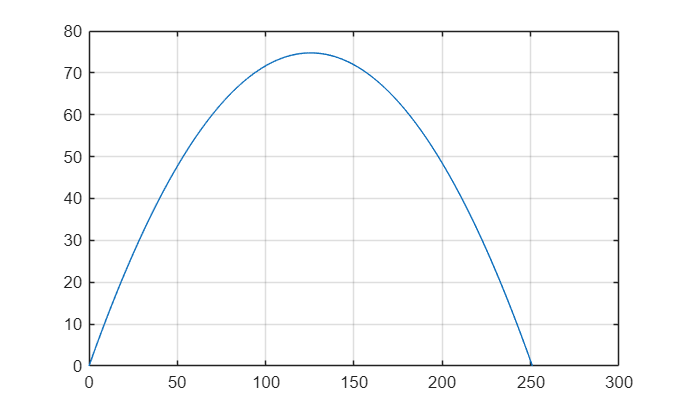


t2 = linspace(0, thit, 100);
x2 = (v02 * cos(A2)) .* t2;
y2 = (v02 * sin(A2)) .* t2 - 0.5 * g2 * t2.^2;
plot(x2, y2)
grid on

3번

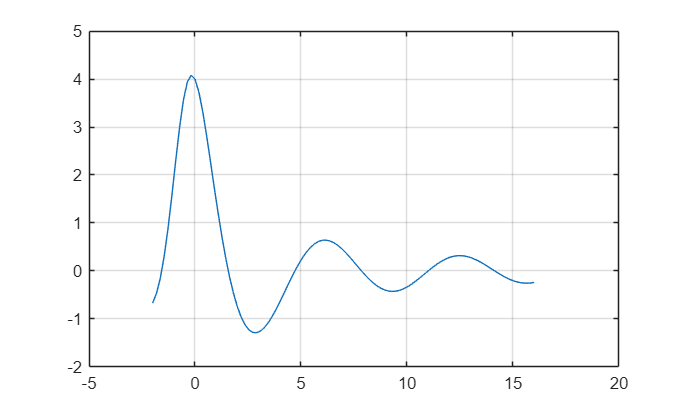

x3 = linspace(-2,16);
f3 = (4*cos(x3)) ./ (x3+exp(-0.75*x3));

figure
plot(x3, f3)
grid on

4번

C4 = [5 4 6; 3 2 4; 6 5 3; 3 5 4; 2 4 3]

C4 =      5     4     6
     3     2     4
     6     5     3
     3     5     4
     2     4     3


prices = [300; 550; 400; 250; 500];

monthly_total = sum(C4,1)

monthly_total =     19    20    20



material_total = sum(C4,2)

material_total =     15
     9
    14
    12
     9



all_total = sum(C4, "all")

all_total = 59

5번

p5_1 = [5,0,-3,7,10];
p5_2 = [4,-7,9,2];
ans_mul = conv(p5_1, p5_2)

ans_mul =     20   -35    33    59   -36   -13   104    20



p5_3 = [5,-7,2,8];
p5_4 = [6,3,-2];
[q5, r5] = deconv(p5_3, p5_4)

q5 =     0.8333   -1.5833


r5 =          0         0    8.4167    4.8333



p5_5 = [36,-8,0,2];
p5_6 = [36,-5,4,-3];
val_x5 = polyval(p5_5, 5) / polyval(p5_6, 5)

val_x5 = 0.9795

7번

bridges(1) = struct('Location', 'Smith St.', 'MaxLoad', 80, 'YearBuilt', 1928, 'DueYear', 2025);
bridges(2) = struct('Location', 'Hope Ave.', 'MaxLoad', 90, 'YearBuilt', 1950, 'DueYear', 2027);
bridges(3) = struct('Location', 'Clark St.', 'MaxLoad', 85, 'YearBuilt', 1933, 'DueYear', 2024);
bridges(4) = struct('Location', 'North Rd.', 'MaxLoad', 100, 'YearBuilt', 1960, 'DueYear', 2023);
bridges

bridges = 다음 필드를 포함한 1×4 struct 배열:
    Location
    MaxLoad
    YearBuilt
    DueYear



bridges(3).DueYear = 2026

bridges = 다음 필드를 포함한 1×4 struct 배열:
    Location
    MaxLoad
    YearBuilt
    DueYear



bridges(5).Location = 'Shore Rd.';
bridges(5).MaxLoad = 85;
bridges(5).YearBuilt = 1997;
bridges(5).DueYear = 2022;
bridges

bridges = 다음 필드를 포함한 1×5 struct 배열:
    Location
    MaxLoad
    YearBuilt
    DueYear
